# IPV Assignment 4 (week 4) 

## **Q2: Implement dilation and erosion in MATLAB**

Morphology is a technique to process ojects in an binary or greyscale image with a structuring element based on the characteristics of its shape.

The structuring element is positioned in all possible locations in the image and it is compared to all neighbours withing its size. The result on each opeation can lead for the SE to 'Fit' when all SE elements are on the object, 'Hit' when at least one element of the SE is on the object or 'Miss' when all elements of the SE are not on the object 

The most basic operators for binary morphology are:

- Erosion. The effect of this operator is for the foreground pixels tho shrink in size.

- Dilation. The opposite of Erosion, the foreground pixels grow in size.

- Opening. Consists of an erosion followed by a dilation. Used to remove small objects from the image.

- Closing. Compromises of a dilation followd by erosion, normally used to fill small gaps.

Here we will experimenting the results of the Erosion and Dilation operators.

I = imread('Untitled.tif');

SESQ = strel('square', 32);
SELV = strel('line', 32, 90);
SELH = strel('line', 32, 0);
SESP = strel('disk', 32);
SELD = strel('line', 32, 45);

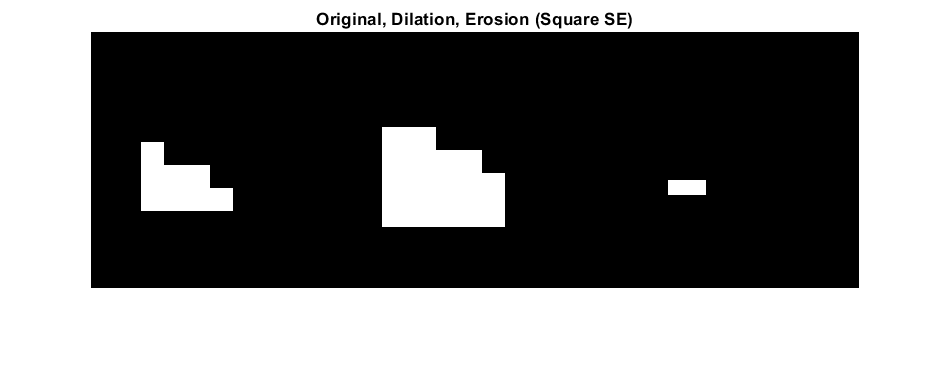

JDSESQ = imdilate(I, SESQ);
JESESQ = imerode(I, SESQ);
imshow([I, JDSESQ, JESESQ]), title('Original, Dilation, Erosion (Square SE)')

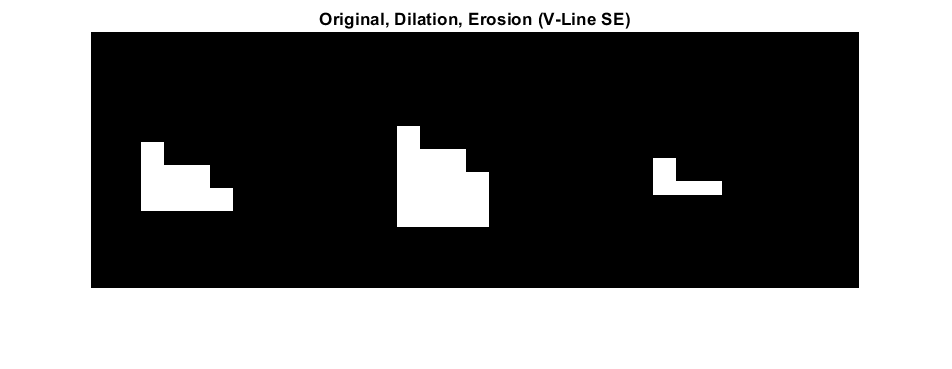

JDSELV = imdilate(I, SELV);
JESELV = imerode(I, SELV);
imshow([I, JDSELV, JESELV]), title('Original, Dilation, Erosion (V-Line SE)')

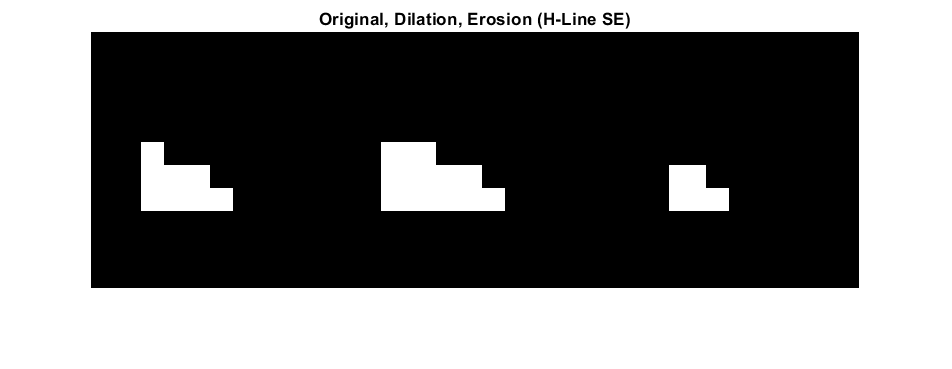

JDSELH = imdilate(I, SELH);
JESELH = imerode(I, SELH);
imshow([I, JDSELH, JESELH]), title('Original, Dilation, Erosion (H-Line SE)')

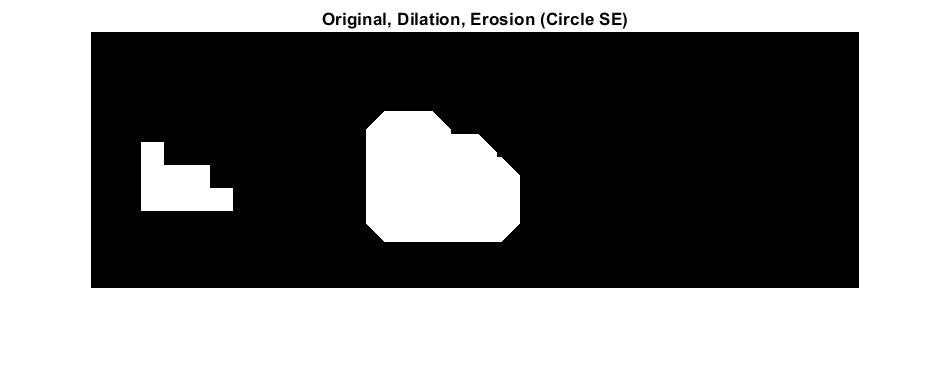

JDSESP = imdilate(I, SESP);
JESESP = imerode(I, SESP);
imshow([I, JDSESP, JESESP]), title('Original, Dilation, Erosion (Circle SE)')

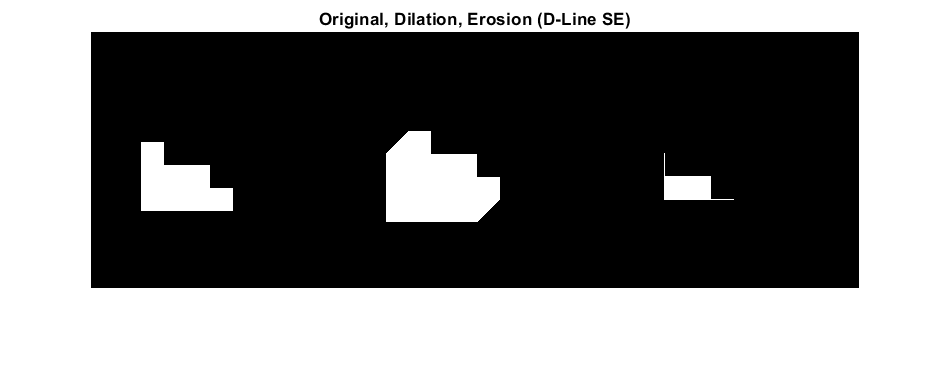

JDSELD = imdilate(I, SELD);
JESELD = imerode(I, SELD);
imshow([I, JDSELD, JESELD]), title('Original, Dilation, Erosion (D-Line SE)')

**Note:**

The image used on the assignment is 8x8 while the image used here is 256x256.

## **Q2: Finish Part 7: Binary Morphology**

 On this section we will be completing Section 7 from this document. First we wil strat by using the the function inside MATLAB and then we will be using the function presented in DIPImage. 

**MATLAB**

Image Opening

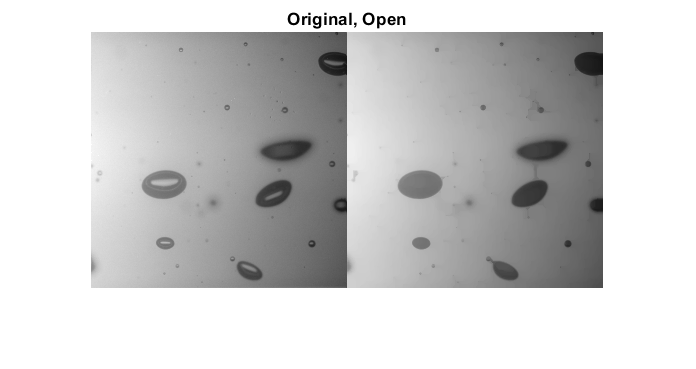

I = imread('bellen.tif');
I2 = imread('srect3.tif');

SESP = strel('disk', 6);

openI = imopen(I, SESP);
openI2 = imopen(I2, SESP);
imshow([I, openI]), title('Original, Open')

This had the efeect of removing the gaps in the objects (Closing Operator), but since in MATLAB the higher the intensity the object, the more is represented as the freground.

Here we can see a better example

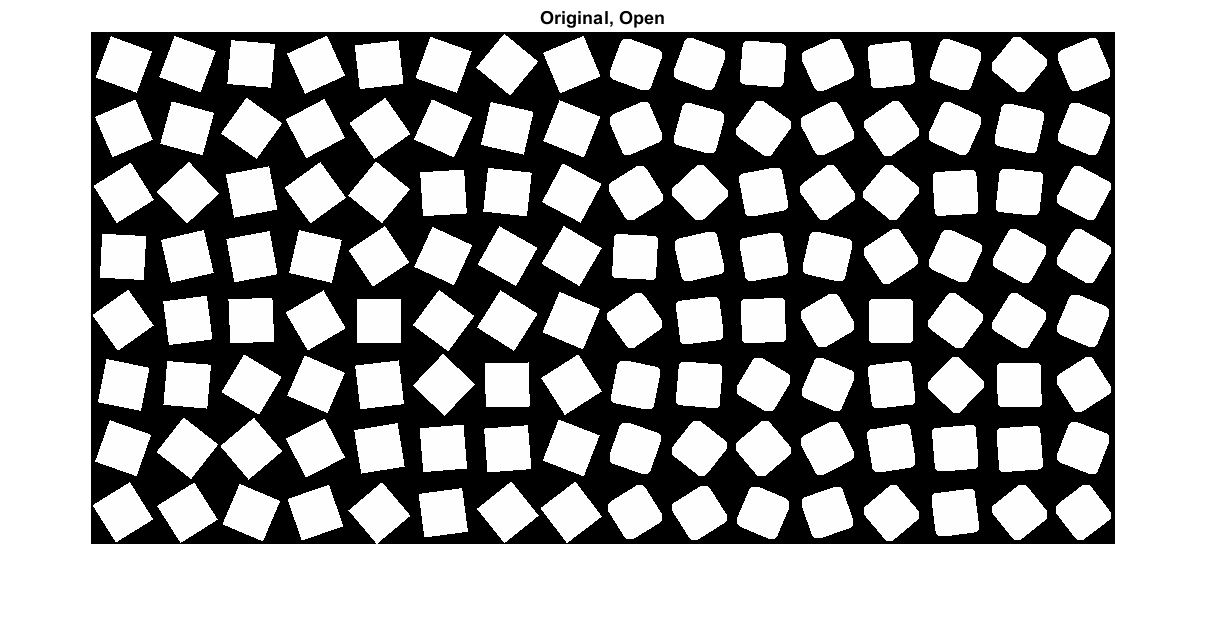

imshow([I2, openI2]), title('Original, Open')

Image Closing:

closeI = imclose(I, SESP);
closeI2 = imclose(I2, SESP);

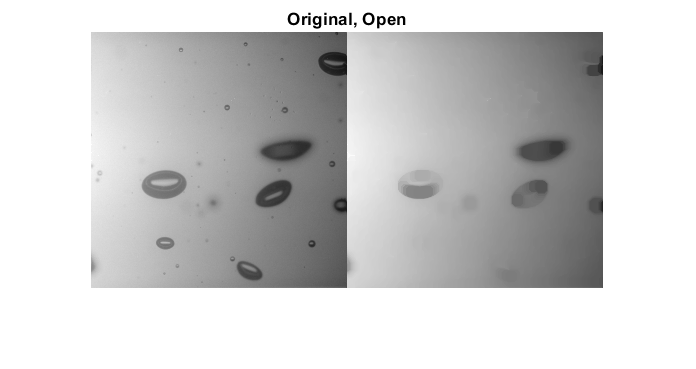

imshow([I, closeI]), title('Original, Open')

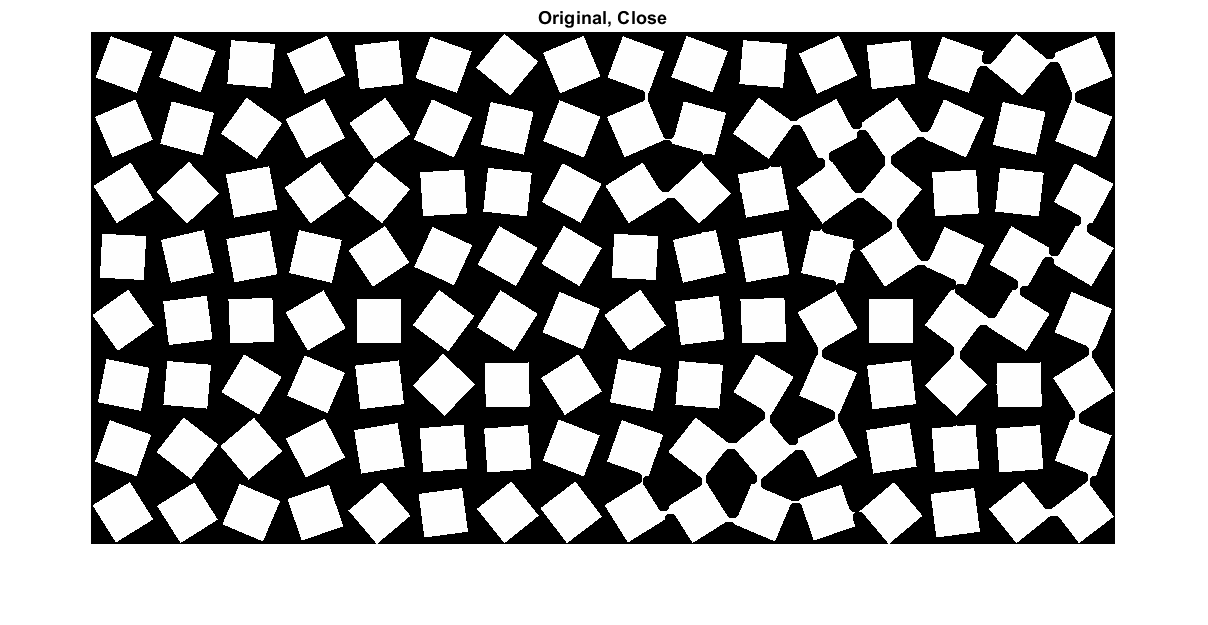

imshow([I2, closeI2]), title('Original, Close')

As we can see, opening the image will result on rounder corner and closing the image results in shaper edges.

**DIPImage**

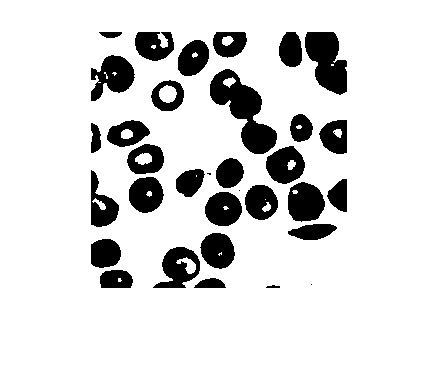

dipimage;
I = imbinarize(imread('sca.tif'));
imshow(I)

Image Opening:

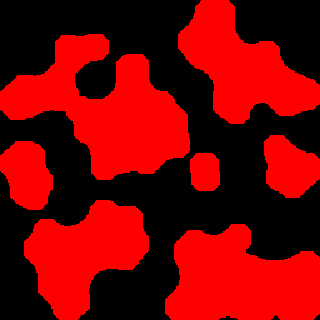

Displayed in figure 12


openI = bopening(I, 10)

Image Closing:

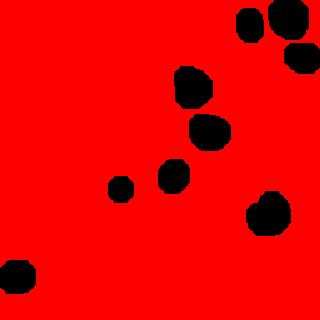

Displayed in figure 13


closeI = bclosing(I, 10)

Image Skeletonization:

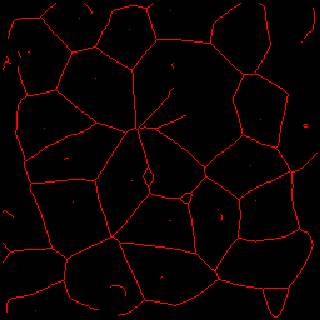

Displayed in figure 14


skletonI = bskeleton(I, 0)

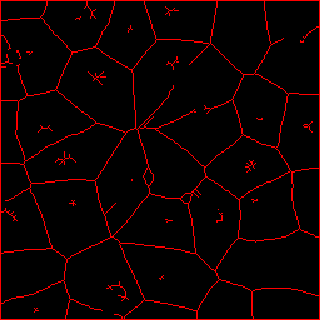

Displayed in figure 15


skletonI = bskeleton(I, 1, '3neighbors')

From the results of the image we can conclude that skeletonization is the process 

## **Q3: Write down all the commands used in Q2B**

**MATLAB**

- strel

- imopen

- imclose

**DIPImage**

- bopening

- bclosing

- bskeleton

## **Q4: Goal: Make your own demo for binary morphology**

**Segmentation**

We use segmentation is used to easily tell the difference between the object and the background.

Since Opening the image smoothes edges and removes small objects from the picture, we used such operation to segment this image. In addition since the foreground objects are round we are using a circular Structuring Element with a small radius in order to keep some of the edges of one of the objects.

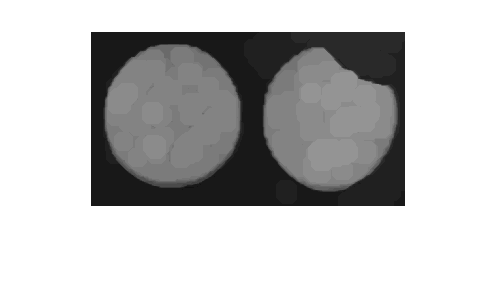

I = imread('cookies.tif');
SE = strel('disk', 10);
openI = imopen(I, SE);
imshow(openI)

## **Q5: Edge detection**

## **Q6: Use morphological operations to implement in MATLAB**